
filename_full = "W:\LWX\Data_Processing\2p\HP08\250313\behavior&imaging\spk_type_HP08_18_2025-03-13.mat"

filename_full = "W:\LWX\Data_Processing\2p\HP08\250313\behavior&imaging\spk_type_HP08_18_2025-03-13.mat"

load(filename_full)

% 
Cue1 = [18,30];
Cue2 = [48,60];
Cue3 = [78,90];
Cue4 = [108,120];
Cue5 = [138,150];
today_type = all_save.type;
spk_type = all_save.raw_spk;

cell_number = length(spk_type);
frontA =  zeros(1,cell_number,13);
BackA = zeros(1,cell_number,13);
frontB = zeros(1,cell_number,13);
BackB = zeros(1,cell_number,13);
frontC = zeros(1,cell_number,13);
midC = zeros(1,cell_number,13);
backC = zeros(1,cell_number,13);
frontempty = zeros(1,cell_number,13);
midempty = zeros(1,cell_number,13);
for k = 1:length(spk_type)
    frontA(1,k,:) = mean([spk_type(1,k,48:60),spk_type(3,k,48:60),spk_type(5,k,48:60)]);
    BackA(1,k,:) = mean([spk_type(2,k,108:120),spk_type(4,k,108:120),spk_type(6,k,108:120)]);

    frontB(1,k,:) = mean([spk_type(2,k,48:60),spk_type(4,k,48:60),spk_type(6,k,48:60)]);
    BackB(1,k,:) = mean([spk_type(1,k,108:120),spk_type(3,k,108:120),spk_type(5,k,108:120)]);

    frontC(1,k,:) = mean([spk_type(1,k,18:30),spk_type(2,k,18:30)]);
    midC(1,k,:) = mean([spk_type(3,k,78:90),spk_type(4,k,78:90)]);
    backC(1,k,:) = mean([spk_type(5,k,138:150),spk_type(6,k,138:150)]);

    frontempty(1,k,:)  = mean([spk_type(3,k,18:30),spk_type(4,k,18:30),spk_type(5,k,18:30),spk_type(6,k,18:30)]);
    midempty(1,k,:)  = mean([spk_type(1,k,78:90),spk_type(2,k,78:90),spk_type(5,k,78:90),spk_type(6,k,78:90)]);
    backempty(1,k,:)  = mean([spk_type(1,k,138:150),spk_type(2,k,138:150),spk_type(3,k,138:150),spk_type(4,k,138:150)]);
end

maxfrontA = zeros(1,cell_number);
maxfrontB = zeros(1,cell_number);
maxbackA = zeros(1,cell_number);
maxbackB = zeros(1,cell_number);
maxfrontC =  zeros(1,cell_number);
maxmidC = zeros(1,cell_number);
maxbackC = zeros(1,cell_number);
maxfrontempty = zeros(1,cell_number);
maxmidempty = zeros(1,cell_number);
maxbackempty = zeros(1,cell_number);
for k = 1:cell_number
    maxfrontA(k) = max(frontA(1,k,:)) ;
    maxfrontB(k) =  max(frontB(1,k,:)) ;
    maxbackA(k) = max(BackA(1,k,:)) ;
    maxbackB(k) = max(BackB(1,k,:)) ;
    maxfrontC(k) = max(frontC(1,k,:)) ;
    maxmidC(k) = max(midC(1,k,:)) ;
    maxbackC(k) = max(backC(1,k,:)) ;
    maxfrontempty(k) = max(frontempty(1,k,:)) ;
    maxmidempty(k) = max(midempty(1,k,:)) ;
    maxbackempty(k) = max(backempty(1,k,:)) ;
end


frontAB= maxfrontA+maxfrontB ;       
BackAB = maxbackB+maxbackA;
frontAE= maxfrontC+maxfrontempty;
midAE= maxmidC+maxmidempty;
backAE= maxbackC+maxbackempty;


% figure;
% histogram(frontAB,'BinWidth',0.5)
% title('A+B')
% figure;
% histogram(BackAB,'BinWidth',0.5)
% title('B+A')

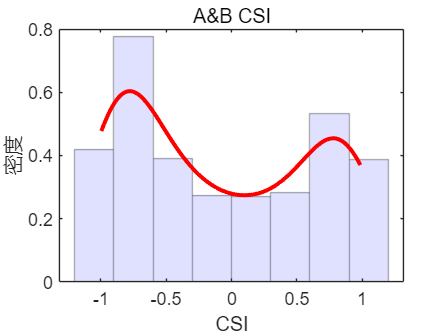


AB_cutoff = 1;
CSI_cutoff = 0.5;

AB_res_cell = find(frontAB>=AB_cutoff);
BA_res_cell = find(BackAB>=AB_cutoff);
AB_sel_all = zeros(1,length(AB_res_cell));
BA_sel_all = zeros(1,length(BA_res_cell));
for i = 1:length(AB_res_cell)
    AB_cell_index = AB_res_cell(i);
    A_response = maxfrontA(AB_cell_index);
    B_response = maxfrontB(AB_cell_index);
    AB_select = (A_response-B_response)/(A_response+B_response);
    AB_sel_all(i) = AB_select;
end

% 绘制概率密度函数图



frontA_select = AB_res_cell(find(AB_sel_all>CSI_cutoff));
frontB_select = AB_res_cell(find(AB_sel_all<-CSI_cutoff));

commonAB = intersect(frontA_select, frontB_select);
disp(commonAB)


for i = 1:length(BA_res_cell)
    BA_cell_index = BA_res_cell(i);
    A_response = maxbackA(BA_cell_index);
    B_response = maxbackB(BA_cell_index);
    BA_select = (A_response-B_response)/(A_response+B_response);
    BA_sel_all(i) = BA_select;
end
backA_select = BA_res_cell(find(BA_sel_all>CSI_cutoff));
backB_select = BA_res_cell(find(BA_sel_all<-CSI_cutoff));

% figure;
% histogram(BA_sel_all,'BinWidth',0.5)
% title('BA CSI')

ABBA_sel_all = [AB_sel_all,BA_sel_all];
figure
histogram(ABBA_sel_all, 'Normalization', 'pdf', 'FaceColor', [0.8, 0.8, 1.0], 'EdgeAlpha', 0.3);

% 计算核密度估计曲线
x = linspace(min(ABBA_sel_all), max(ABBA_sel_all), 100);
y = ksdensity(ABBA_sel_all, x);

% 添加核密度估计曲线
hold on;
plot(x, y, 'r-', 'LineWidth', 2);
hold off;
title('A&B CSI');
xlabel('CSI');
ylabel('概率密度');
ylabel('密度');


commonBA = intersect(backA_select, backB_select);
disp(commonBA)

A_cell =  unique([frontA_select, backA_select]);
Asame_cell = intersect(frontA_select, backA_select);

B_cell = unique([frontB_select, backB_select]);
Bsame_cell = intersect(frontB_select, backB_select);

AB_cell = unique([A_cell,B_cell]);
ABsame_cell = intersect(A_cell, B_cell);

A_Bsame_cell = unique([Asame_cell, Bsame_cell]);

A_percent = numel(A_cell)/cell_number;
B_percent = numel(B_cell)/cell_number;
Asame_percent = numel(Asame_cell)/cell_number;
Bsame_percent = numel(Bsame_cell)/cell_number;
AB_percent = numel(AB_cell)/cell_number;
ABsame_percent = numel(ABsame_cell)/cell_number;
A_Bsame_percent = numel(A_Bsame_cell)/cell_number;


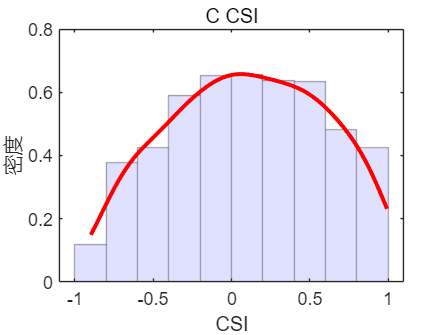

% figure;
% histogram(frontAE,'BinWidth',0.5)
% figure;
% histogram(midAE,'BinWidth',0.5)
% figure;
% histogram(backAE,'BinWidth',0.5)

C_cutoff = 1;
frontC_res_cell = find(frontAE >= C_cutoff);
midC_res_cell = find(midAE >= C_cutoff);
backC_res_cell = find(backAE >= C_cutoff);

fC_sel_all = zeros(1,length(frontC_res_cell));
mC_sel_all = zeros(1,length(midC_res_cell));
bC_sel_all = zeros(1,length(backC_res_cell));

for i = 1:length(frontC_res_cell)
    frontC_cell_index = frontC_res_cell(i);
    C_response = maxfrontC(frontC_cell_index);
    Empty_response = maxfrontempty(frontC_cell_index);
    frontC_select = (C_response-Empty_response)/(C_response+Empty_response);
    fC_sel_all(i) = frontC_select;
end
%     figure;
%     histogram(fC_sel_all,'BinWidth',0.5)
%     title('fC CSI')
fc_cell = frontC_res_cell(find(fC_sel_all>0.5));

for i = 1:length(midC_res_cell)
    midC_cell_index = midC_res_cell(i);
    C_response = maxmidC(midC_cell_index);
    Empty_response = maxmidempty(midC_cell_index);
    midC_select = (C_response-Empty_response)/(C_response+Empty_response);
    mC_sel_all(i) = midC_select;
end
%     figure;
%     histogram(mC_sel_all,'BinWidth',0.5)
%     title('mC CSI')
mc_cell = midC_res_cell(find(mC_sel_all>0.5));


for i = 1:length(backC_res_cell)
    backC_cell_index = backC_res_cell(i);
    C_response = maxbackC(backC_cell_index);
    Empty_response = maxbackempty(backC_cell_index);
    backC_select = (C_response-Empty_response)/(C_response+Empty_response);
    bC_sel_all(i) = backC_select;
end
%     figure;
%     histogram(bC_sel_all,'BinWidth',0.5)
%     title('bC CSI')
bc_cell = backC_res_cell(find(bC_sel_all>0.5));

CCC_sel_all = [fC_sel_all,mC_sel_all,bC_sel_all];
figure
histogram(CCC_sel_all, 'Normalization', 'pdf', 'FaceColor', [0.8, 0.8, 1.0], 'EdgeAlpha', 0.3);

% 计算核密度估计曲线
x = linspace(min(CCC_sel_all), max(CCC_sel_all), 100);
y = ksdensity(CCC_sel_all, x);

% 添加核密度估计曲线
hold on;
plot(x, y, 'r-', 'LineWidth', 2);
hold off;
title('C CSI');
xlabel('CSI');
ylabel('概率密度');
ylabel('密度');


C_cell =  unique([fc_cell, mc_cell,bc_cell]);
Csame_cell1 = intersect(fc_cell,mc_cell);
Csame_cell = intersect(bc_cell,Csame_cell1);
C_percent = numel(C_cell)/cell_number;
Csame_percent = numel(C_cell)/cell_number;